clc; clear; close all;

%% Sensor / Target initialize

% 패시브 소나와 EKF를 이용한 방위각 기반 타겟 위치 추정 알고리즘
% 두개의 어뢰와 모선에 있는 소나 센서를 이용
% State=[x y z vx vy vz]'
% measurement=[b e]'각각 방위각, 양각 
% 필터 :  EKF
load("BadTrajec.mat");% trajectory 파일들은 따로 생성 후 관리. 이 파일 안에 trajectories.target 형태로 저장.

%% Target,Mothership and Torpedoes initialization
target=initializeTarget([90 -20],15,DOPgoodtrajectories1.target); % [azimuth elevation](deg) velocity trajectory
mship=initializeTracker(20,40000,1,target,DOPgoodtrajectories1.mship);%v,maxD,noise(deg),target,trajectory
torpedo1=initializeTracker(20,40000,1,target,DOPgoodtrajectories1.torpedo1);%v,maxD,noise(deg),target,trajectory
torpedo2=initializeTracker(20,40000,1,target,DOPgoodtrajectories1.torpedo2);%v,maxD,noise(deg),target,trajectory


%% Uncertainty Area Calculation
th=200;%threshold for combining

%% Visualization

[uncertainArea, condNum] = findUncertaintyArea(mship.sonar, torpedo1.sonar, torpedo2.sonar, th);

   200



condNum = 5.5087

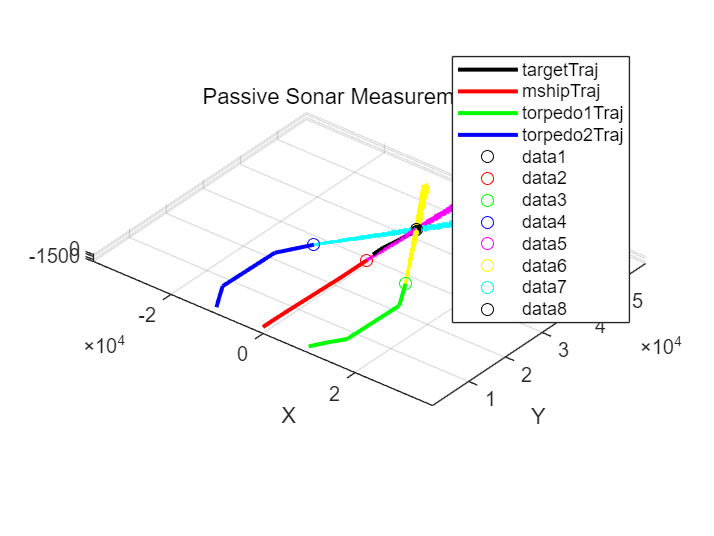

   200



condNum = 7.0114

i = 1

   200



condNum = 8.2208

i = 2

   200



condNum = 34.4555

i = 3

   200



condNum = 6.9309

i = 4

   200



condNum = 5.2397

i = 5

   200



condNum = 5.6146

i = 6

   200



condNum = 6.7870

i = 7

   200



condNum = 9.3051

i = 8

   200



condNum = 11.4737

i = 9

   200



condNum = 8.1028

i = 10

   200



condNum = 12.0168

i = 11

   200



condNum = 4.0801

i = 12

   200



condNum = 9.4799

i = 13

   200



condNum = 9.5148

i = 14

   200



condNum = 8.5860

i = 15

   200



condNum = 16.2116

i = 16

   200



condNum = 8.8136

i = 17

   200



condNum = 4.2729

i = 18

   200



condNum = 6.8376

i = 19

   200



condNum = 9.0358

i = 20

   200



condNum = 14.1306

i = 21

   200



condNum = 6.8004

i = 22

   200



condNum = 8.7658

i = 23

   200



condNum = 3.5174

i = 24

   200



condNum = 14.3603

i = 25

   200



condNum = 10.2030

i = 26

   200



condNum = 14.3967

i = 27

   200



condNum = 10.4958

i = 28

   200



condNum = 15.6416

i = 29

   200



condNum = 1.9890

i = 30

   200



condNum = 15.6107

i = 31

   200



condNum = 4.4013

i = 32

   200



condNum = 8.4238

i = 33

   200



condNum = 4.9720

i = 34

   200



condNum = 9.4818

i = 35

   200



condNum = 3.0040

i = 36

   200



condNum = 2.4579

i = 37

   200



condNum = 4.5781

i = 38

   200



condNum = 12.7468

i = 39

   200



condNum = 3.7736

i = 40

   200



condNum = 8.8217

i = 41

   200



condNum = 4.4439

i = 42

   200



condNum = 19.9147

i = 43

   200



condNum = 2.1573

i = 44

   200



condNum = 5.5857

i = 45

   200



condNum = 5.6111

i = 46

   200



condNum = 26.3173

i = 47

   200



condNum = 5.6487

i = 48

   200



condNum = 3.8077

i = 49

   200



condNum = 7.6670

i = 50

   200



condNum = 7.8631

i = 51

   200



condNum = 3.6822

i = 52

   200



condNum = 4.6709

i = 53

   200



condNum = 77.1500

i = 54

   200



condNum = 6.5477

i = 55

   200



condNum = 11.9803

i = 56

   200



condNum = 2.5958

i = 57

   200



condNum = 31.1566

i = 58

   200



condNum = 7.1939

i = 59

   200



condNum = 2.7555

i = 60

   200



condNum = 4.9985

i = 61

   200



condNum = 2.8674

i = 62

   200



condNum = 5.4957

i = 63

   200



condNum = 12.6979

i = 64

   200



condNum = 6.1220

i = 65

   200



condNum = 10.5224

i = 66

   200



condNum = 8.3617

i = 67

   200



condNum = 7.9206

i = 68

   200



condNum = 15.4408

i = 69

   200



condNum = 7.2852

i = 70

   200



condNum = 7.0784

i = 71

   200



condNum = 7.1750

i = 72

   200



condNum = 3.6066

i = 73

   200



condNum = 5.4970

i = 74

   200



condNum = 3.0721

i = 75

   200



condNum = 3.9362

i = 76

   200



condNum = 5.2174

i = 77

   200



condNum = 11.9071

i = 78

   200



condNum = 9.4787

i = 79

   200



condNum = 6.9374

i = 80

   200



condNum = 10.1336

i = 81

   200



condNum = 10.8992

i = 82

   200



condNum = 10.3715

i = 83

   200



condNum = 7.6244

i = 84

   200



condNum = 8.8069

i = 85

   200



condNum = 6.3757

i = 86

   200



condNum = 11.6674

i = 87

   200



condNum = 6.3221

i = 88

   200



condNum = 7.3356

i = 89

   200



condNum = 20.0896

i = 90

   200



condNum = 4.9885

i = 91

   200



condNum = 5.6544

i = 92

   200



condNum = 9.5749

i = 93

   200



condNum = 5.3636

i = 94

   200



condNum = 4.9173

i = 95

   200



condNum = 6.9307

i = 96

   200



condNum = 12.5789

i = 97

   200



condNum = 12.8843

i = 98

   200



condNum = 4.7995

i = 99

   200



condNum = 3.7114

i = 100

   200



condNum = 6.2318

i = 101

   200



condNum = 5.7120

i = 102

   200



condNum = 29.6477

i = 103

   200



condNum = 12.4222

i = 104

   200



condNum = 5.3650

i = 105

   200



condNum = 5.2010

i = 106

   200



condNum = 6.2015

i = 107

   200



condNum = 18.9932

i = 108

   200



condNum = 5.8929

i = 109

   200



condNum = 13.4350

i = 110

   200



condNum = 5.0436

i = 111

   200



condNum = 27.1053

i = 112

   200



condNum = 5.5544

i = 113

   200



condNum = 7.3068

i = 114

   200



condNum = 3.6668

i = 115

   200



condNum = 8.0435

i = 116

   200



condNum = 9.3683

i = 117

   200



condNum = 7.7948

i = 118

   200



condNum = 4.9380

i = 119

   200



condNum = 11.0646

i = 120

   200



condNum = 17.0837

i = 121

   200



condNum = 8.6746

i = 122

   200



condNum = 5.6182

i = 123

   200



condNum = 6.7398

i = 124

   200



condNum = 8.0542

i = 125

   200



condNum = 4.4366

i = 126

   200



condNum = 7.1388

i = 127

   200



condNum = 12.0999

i = 128

   200



condNum = 9.5891

i = 129

   200



condNum = 16.5751

i = 130

   200



condNum = 12.8271

i = 131

   200



condNum = 4.3809

i = 132

   200



condNum = 6.1781

i = 133

   200



condNum = 8.9248

i = 134

   200



condNum = 3.6422

i = 135

   200



condNum = 5.3427

i = 136

   200



condNum = 10.2375

i = 137

   200



condNum = 8.0891

i = 138

   200



condNum = 13.4717

i = 139

   200



condNum = 20.2451

i = 140

   200



condNum = 118.9281

i = 141

   200



condNum = 8.2839

i = 142

   200



condNum = 18.0142

i = 143

   200



condNum = 7.1259

i = 144

   200



condNum = 7.5354

i = 145

   200



condNum = 8.8779

i = 146

   200



condNum = 3.4217

i = 147

   200



condNum = 17.8120

i = 148

   200



condNum = 11.5068

i = 149

   200



condNum = 4.8069

i = 150

   200



condNum = 10.1279

i = 151

   200



condNum = 11.1206

i = 152

   200



condNum = 7.4930

i = 153

   200



condNum = 8.6846

i = 154

   200



condNum = 12.6731

i = 155

   200



condNum = 8.2793

i = 156

   200



condNum = 5.9042

i = 157

   200



condNum = 13.4875

i = 158

   200



condNum = 14.6982

i = 159

   200



condNum = 3.9767

i = 160

   200



condNum = 6.3225

i = 161

   200



condNum = 10.1244

i = 162

   200



condNum = 13.5446

i = 163

   200



condNum = 10.3720

i = 164

   200



condNum = 5.5478

i = 165

   200



condNum = 5.5007

i = 166

   200



condNum = 8.9272

i = 167

   200



condNum = 16.1710

i = 168

   200



condNum = 10.6116

i = 169

   200



condNum = 8.3337

i = 170

   200



condNum = 6.9559

i = 171

   200



condNum = 19.9979

i = 172

   200



condNum = 11.8991

i = 173

   200



condNum = 21.8673

i = 174

   200



condNum = 13.1986

i = 175

   200



condNum = 11.7747

i = 176

   200



condNum = 9.3397

i = 177

   200



condNum = 4.1081

i = 178

   200



condNum = 17.4363

i = 179

   200



condNum = 16.4201

i = 180

   200



condNum = 3.8806

i = 181

   200



condNum = 8.0241

i = 182

   200



condNum = 17.4348

i = 183

   200



condNum = 15.6406

i = 184

   200



condNum = 8.8283

i = 185

   200



condNum = 6.2365

i = 186

   200



condNum = 6.9584

i = 187

   200



condNum = 30.6300

i = 188

   200



condNum = 3.1059

i = 189

   200



condNum = 7.5487

i = 190

   200



condNum = 13.5613

i = 191

   200



condNum = 9.7493

i = 192

   200



condNum = 8.1726

i = 193

   200



condNum = 8.3605

i = 194

   200



condNum = 20.1540

i = 195

   200



condNum = 8.8485

i = 196

   200



condNum = 5.5586

i = 197

   200



condNum = 5.2239

i = 198

   200



condNum = 10.7531

i = 199

   200



condNum = 27.1007

i = 200

   200



condNum = 3.7253

i = 201

   200



condNum = 9.7215

i = 202

   200



condNum = 48.4658

i = 203

   200



condNum = 7.4705

i = 204

   200



condNum = 13.8612

i = 205

   200



condNum = 4.2412

i = 206

   200



condNum = 10.3383

i = 207

   200



condNum = 9.3641

i = 208

   200



condNum = 7.4528

i = 209

   200



condNum = 7.3169

i = 210

   200



condNum = 10.1246

i = 211

   200



condNum = 6.0331

i = 212

   200



condNum = 11.0214

i = 213

   200



condNum = 4.9175

i = 214

   200



condNum = 10.7238

i = 215

   200



condNum = 6.5459

i = 216

   200



condNum = 8.0339

i = 217

   200



condNum = 6.0162

i = 218

   200



condNum = 25.1538

i = 219

   200



condNum = 5.0019

i = 220

   200



condNum = 15.4871

i = 221

   200



condNum = 7.8879

i = 222

   200



condNum = 9.8674

i = 223

   200



condNum = 4.7037

i = 224

   200



condNum = 4.7373

i = 225

   200



condNum = 8.0715

i = 226

   200



condNum = 11.5827

i = 227

   200



condNum = 15.5860

i = 228

   200



condNum = 13.7069

i = 229

   200



condNum = 6.4042

i = 230

   200



condNum = 27.2189

i = 231

   200



condNum = 6.6197

i = 232

   200



condNum = 16.4752

i = 233

   200



condNum = 4.6156

i = 234

   200



condNum = 6.6680

i = 235

   200



condNum = 5.6432

i = 236

   200



condNum = 22.7000

i = 237

   200



condNum = 9.2219

i = 238

   200



condNum = 8.0408

i = 239

   200



condNum = 22.7115

i = 240

   200



condNum = 9.2656

i = 241

   200



condNum = 7.1949

i = 242

   200



condNum = 14.7957

i = 243

   200



condNum = 11.1834

i = 244

   200



condNum = 9.0013

i = 245

   200



condNum = 9.3675

i = 246

   200



condNum = 9.7388

i = 247

   200



condNum = 12.9270

i = 248

   200



condNum = 5.7618

i = 249

   200



condNum = 7.6645

i = 250

   200



condNum = 5.1525

i = 251

   200



condNum = 9.8424

i = 252

   200



condNum = 9.7397

i = 253

   200



condNum = 12.2121

i = 254

   200



condNum = 14.9597

i = 255

   200



condNum = 5.6828

i = 256

   200



condNum = 8.5446

i = 257

   200



condNum = 14.2773

i = 258

   200



condNum = 12.6275

i = 259

   200



condNum = 4.9052

i = 260

   200



condNum = 14.5959

i = 261

   200



condNum = 14.2569

i = 262

   200



condNum = 14.5123

i = 263

   200



condNum = 8.1279

i = 264

   200



condNum = 10.6231

i = 265

   200



condNum = 7.0290

i = 266

   200



condNum = 4.2096

i = 267

   200



condNum = 22.4923

i = 268

   200



condNum = 5.5123

i = 269

   200



condNum = 4.6699

i = 270

   200



condNum = 7.4449

i = 271

   200



condNum = 15.0768

i = 272

   200



condNum = 7.6250

i = 273

   200



condNum = 15.4327

i = 274

   200



condNum = 12.9382

i = 275

   200



condNum = 10.9959

i = 276

   200



condNum = 4.4653

i = 277

   200



condNum = 11.2183

i = 278

   200



condNum = 27.4186

i = 279

   200



condNum = 4.5285

i = 280

   200



condNum = 11.2495

i = 281

   200



condNum = 10.2420

i = 282

   200



condNum = 11.7391

i = 283

   200



condNum = 6.4213

i = 284

   200



condNum = 13.8891

i = 285

   200



condNum = 7.8040

i = 286

   200



condNum = 11.3920

i = 287

   200



condNum = 10.4674

i = 288

   200



condNum = 10.2177

i = 289

   200



condNum = 6.3375

i = 290

   200



condNum = 7.0420

i = 291

   200



condNum = 8.8576

i = 292

   200



condNum = 15.0808

i = 293

   200



condNum = 6.8457

i = 294

   200



condNum = 10.8952

i = 295

   200



condNum = 6.4778

i = 296

   200



condNum = 6.8669

i = 297

   200



condNum = 10.7086

i = 298

   200



condNum = 14.9052

i = 299

   200



condNum = 8.6444

i = 300

   200



condNum = 6.2253

i = 301

   200



condNum = 6.7620

i = 302

   200



condNum = 13.5322

i = 303

   200



condNum = 42.8217

i = 304

   200



condNum = 6.6052

i = 305

   200



condNum = 5.8616

i = 306

   200



condNum = 7.8339

i = 307

   200



condNum = 6.7967

i = 308

   200



condNum = 4.5193

i = 309

   200



condNum = 10.3963

i = 310

   200



condNum = 2.8940

i = 311

   200



condNum = 3.5432

i = 312

   200



condNum = 4.9525

i = 313

   200



condNum = 12.1684

i = 314

   200



condNum = 10.2985

i = 315

   200



condNum = 4.1895

i = 316

   200



condNum = 3.8733

i = 317

   200



condNum = 12.3998

i = 318

   200



condNum = 55.9318

i = 319

   200



condNum = 14.8696

i = 320

   200



condNum = 4.9535

i = 321

   200



condNum = 16.4252

i = 322

   200



condNum = 21.8966

i = 323

   200



condNum = 6.7214

i = 324

   200



condNum = 6.5289

i = 325

   200



condNum = 4.8463

i = 326

   200



condNum = 7.5553

i = 327

   200



condNum = 5.7431

i = 328

   200



condNum = 4.5613

i = 329

   200



condNum = 7.3131

i = 330

   200



condNum = 5.1656

i = 331

   200



condNum = 3.9815

i = 332

   200



condNum = 12.2649

i = 333

   200



condNum = 9.8547

i = 334

   200



condNum = 8.2645

i = 335

   200



condNum = 8.7821

i = 336

   200



condNum = 3.0267

i = 337

   200



condNum = 4.4918

i = 338

   200



condNum = 11.3076

i = 339

   200



condNum = 7.0357

i = 340

   200



condNum = 14.8029

i = 341

   200



condNum = 6.5978

i = 342

   200



condNum = 6.7628

i = 343

   200



condNum = 20.1997

i = 344

   200



condNum = 21.0599

i = 345

   200



condNum = 2.5401

i = 346

   200



condNum = 7.9776

i = 347

   200



condNum = 11.2260

i = 348

   200



condNum = 5.1270

i = 349

   200



condNum = 17.2569

i = 350

   200



condNum = 10.1062

i = 351

   200



condNum = 9.9637

i = 352

   200



condNum = 9.1274

i = 353

   200



condNum = 8.6181

i = 354

   200



condNum = 10.9267

i = 355

   200



condNum = 10.7918

i = 356

   200



condNum = 8.0592

i = 357

   200



condNum = 10.1025

i = 358

   200



condNum = 12.8688

i = 359

   200



condNum = 6.7475

i = 360

   200



condNum = 5.9572

i = 361

   200



condNum = 4.6485

i = 362

   200



condNum = 6.3887

i = 363

   200



condNum = 6.1439

i = 364

   200



condNum = 7.7274

i = 365

   200



condNum = 3.9492

i = 366

   200



condNum = 4.2125

i = 367

   200



condNum = 2.3950

i = 368

   200



condNum = 16.7336

i = 369

   200



condNum = 7.1080

i = 370

   200



condNum = 7.9327

i = 371

   200



condNum = 12.3390

i = 372

   200



condNum = 4.8463

i = 373

   200



condNum = 1.6582

i = 374

   200



condNum = 4.9625

i = 375

   200



condNum = 10.5619

i = 376

   200



condNum = 6.7088

i = 377

   200



condNum = 7.2647

i = 378

   200



condNum = 23.0506

i = 379

   200



condNum = 6.5910

i = 380

   200



condNum = 3.1155

i = 381

   200



condNum = 11.0884

i = 382

   200



condNum = 9.6349

i = 383

   200



condNum = 5.7412

i = 384

   200



condNum = 11.8229

i = 385

   200



condNum = 10.7841

i = 386

   200



condNum = 15.2043

i = 387

   200



condNum = 4.6093

i = 388

   200



condNum = 8.9183

i = 389

   200



condNum = 15.7002

i = 390

   200



condNum = 6.7668

i = 391

   200



condNum = 8.9096

i = 392

   200



condNum = 5.7736

i = 393

   200



condNum = 5.9023

i = 394

   200



condNum = 7.0250

i = 395

   200



condNum = 8.5326

i = 396

   200



condNum = 15.1596

i = 397

   200



condNum = 11.1180

i = 398

   200



condNum = 7.3091

i = 399

   200



condNum = 16.9622

i = 400

   200



condNum = 3.0914

i = 401

   200



condNum = 5.8976

i = 402

   200



condNum = 4.5430

i = 403

   200



condNum = 26.6571

i = 404

   200



condNum = 8.3222

i = 405

   200



condNum = 8.9125

i = 406

   200



condNum = 5.2046

i = 407

   200



condNum = 11.5251

i = 408

   200



condNum = 6.5975

i = 409

   200



condNum = 20.8657

i = 410

   200



condNum = 17.4983

i = 411

   200



condNum = 5.9888

i = 412

   200



condNum = 6.8567

i = 413

   200



condNum = 14.8187

i = 414

   200



condNum = 6.9469

i = 415

   200



condNum = 15.2832

i = 416

   200



condNum = 3.6079

i = 417

   200



condNum = 8.0936

i = 418

   200



condNum = 5.7774

i = 419

   200



condNum = 4.6702

i = 420

   200



condNum = 11.9480

i = 421

   200



condNum = 4.6808

i = 422

   200



condNum = 21.5230

i = 423

   200



condNum = 5.1839

i = 424

   200



condNum = 7.7916

i = 425

   200



condNum = 6.3692

i = 426

   200



condNum = 8.8416

i = 427

   200



condNum = 9.0856

i = 428

   200



condNum = 13.5137

i = 429

   200



condNum = 10.0188

i = 430

   200



condNum = 16.2180

i = 431

   200



condNum = 8.1636

i = 432

   200



condNum = 36.2853

i = 433

   200



condNum = 20.3874

i = 434

   200



condNum = 11.1954

i = 435

   200



condNum = 5.6752

i = 436

   200



condNum = 16.4697

i = 437

   200



condNum = 4.5727

i = 438

   200



condNum = 4.9679

i = 439

   200



condNum = 8.6571

i = 440

   200



condNum = 6.2769

i = 441

   200



condNum = 6.1074

i = 442

   200



condNum = 9.3053

i = 443

   200



condNum = 5.8617

i = 444

   200



condNum = 3.4663

i = 445

   200



condNum = 12.6960

i = 446

   200



condNum = 5.0356

i = 447

   200



condNum = 11.2327

i = 448

   200



condNum = 4.3178

i = 449

   200



condNum = 10.1381

i = 450

   200



condNum = 20.9789

i = 451

   200



condNum = 11.7457

i = 452

   200



condNum = 21.0902

i = 453

   200



condNum = 11.5959

i = 454

   200



condNum = 11.2530

i = 455

   200



condNum = 10.5716

i = 456

   200



condNum = 6.1416

i = 457

   200



condNum = 8.4601

i = 458

   200



condNum = 19.1265

i = 459

   200



condNum = 8.2998

i = 460

   200



condNum = 7.6966

i = 461

   200



condNum = 5.1145

i = 462

   200



condNum = 5.4766

i = 463

   200



condNum = 5.4410

i = 464

   200



condNum = 8.5570

i = 465

   200



condNum = 8.4508

i = 466

   200



condNum = 14.8837

i = 467

   200



condNum = 10.5022

i = 468

   200



condNum = 2.9678

i = 469

   200



condNum = 8.2887

i = 470

   200



condNum = 3.4794

i = 471

   200



condNum = 59.6077

i = 472

   200



condNum = 10.2246

i = 473

   200



condNum = 3.8767

i = 474

   200



condNum = 9.4107

i = 475

   200



condNum = 5.6620

i = 476

   200



condNum = 10.5238

i = 477

   200



condNum = 9.7783

i = 478

   200



condNum = 8.4782

i = 479

   200



condNum = 4.9893

i = 480

   200



condNum = 5.7343

i = 481

   200



condNum = 5.0451

i = 482

   200



condNum = 20.2429

i = 483

   200



condNum = 15.1951

i = 484

   200



condNum = 4.8451

i = 485

   200



condNum = 12.8483

i = 486

   200



condNum = 12.2902

i = 487

   200



condNum = 6.6683

i = 488

   200



condNum = 6.5680

i = 489

   200



condNum = 10.4889

i = 490

   200



condNum = 5.9373

i = 491

   200



condNum = 10.2181

i = 492

   200



condNum = 2.8477

i = 493

   200



condNum = 9.6264

i = 494

   200



condNum = 4.4949

i = 495

   200



condNum = 2.8940

i = 496

   200



condNum = 3.4270

i = 497

   200



condNum = 4.0796

i = 498

   200



condNum = 9.0026

i = 499

   200



condNum = 14.2674

i = 500

   200



condNum = 9.5358

i = 501

   200



condNum = 13.8093

i = 502

   200



condNum = 2.2837

i = 503

   200



condNum = 6.6003

i = 504

   200



condNum = 8.6097

i = 505

   200



condNum = 11.6346

i = 506

   200



condNum = 11.4088

i = 507

   200



condNum = 27.5607

i = 508

   200



condNum = 5.9994

i = 509

   200



condNum = 14.6276

i = 510

   200



condNum = 13.2910

i = 511

   200



condNum = 7.4983

i = 512

   200



condNum = 11.6409

i = 513

   200



condNum = 13.1200

i = 514

   200



condNum = 8.4584

i = 515

   200



condNum = 3.9000

i = 516

   200



condNum = 7.8222

i = 517

   200



condNum = 10.5939

i = 518

   200



condNum = 11.1103

i = 519

   200



condNum = 5.0454

i = 520

   200



condNum = 7.8093

i = 521

   200



condNum = 9.1802

i = 522

   200



condNum = 5.2562

i = 523

   200



condNum = 6.2898

i = 524

   200



condNum = 7.7800

i = 525

   200



condNum = 4.9037

i = 526

   200



condNum = 5.9887

i = 527

   200



condNum = 8.1465

i = 528

   200



condNum = 10.2558

i = 529

   200



condNum = 9.4087

i = 530

   200



condNum = 4.4349

i = 531

   200



condNum = 6.6751

i = 532

   200



condNum = 5.6376

i = 533

   200



condNum = 8.9287

i = 534

   200



condNum = 15.4650

i = 535

   200



condNum = 7.6550

i = 536

   200



condNum = 4.6317

i = 537

   200



condNum = 5.1115

i = 538

   200



condNum = 4.1124

i = 539

   200



condNum = 9.8628

i = 540

   200



condNum = 9.5850

i = 541

   200



condNum = 20.9370

i = 542

   200



condNum = 15.7944

i = 543

   200



condNum = 3.0482

i = 544

   200



condNum = 3.2953

i = 545

   200



condNum = 5.9751

i = 546

   200



condNum = 25.2737

i = 547

   200



condNum = 5.6035

i = 548

   200



condNum = 7.1919

i = 549

   200



condNum = 5.7958

i = 550

   200



condNum = 6.7381

i = 551

   200



condNum = 25.6590

i = 552

   200



condNum = 8.3544

i = 553

   200



condNum = 11.4842

i = 554

   200



condNum = 4.0199

i = 555

   200



condNum = 12.8927

i = 556

   200



condNum = 7.8524

i = 557

   200



condNum = 11.3086

i = 558

   200



condNum = 3.6190

i = 559

   200



condNum = 12.7379

i = 560

   200



condNum = 10.4760

i = 561

   200



condNum = 20.8248

i = 562

   200



condNum = 7.5745

i = 563

   200



condNum = 4.8149

i = 564

   200



condNum = 6.2147

i = 565

   200



condNum = 5.9352

i = 566

   200



condNum = 6.3530

i = 567

   200



condNum = 5.1729

i = 568

   200



condNum = 15.5467

i = 569

   200



condNum = 11.0641

i = 570

   200



condNum = 9.0552

i = 571

   200



condNum = 8.6270

i = 572

   200



condNum = 25.9743

i = 573

   200



condNum = 13.4329

i = 574

   200



condNum = 7.6288

i = 575

   200



condNum = 3.2527

i = 576

   200



condNum = 6.1092

i = 577

   200



condNum = 5.4149

i = 578

   200



condNum = 5.7233

i = 579

   200



condNum = 7.4026

i = 580

   200



condNum = 5.1718

i = 581

   200



condNum = 15.6658

i = 582

   200



condNum = 8.0504

i = 583

   200



condNum = 11.3556

i = 584

   200



condNum = 3.8044

i = 585

   200



condNum = 14.4491

i = 586

   200



condNum = 7.7188

i = 587

   200



condNum = 7.2524

i = 588

   200



condNum = 9.8495

i = 589

   200



condNum = 7.7211

i = 590

   200



condNum = 15.2548

i = 591

   200



condNum = 2.6986

i = 592

   200



condNum = 7.5191

i = 593

   200



condNum = 19.5198

i = 594

   200



condNum = 6.9720

i = 595

   200



condNum = 8.1258

i = 596

   200



condNum = 6.4175

i = 597

   200



condNum = 3.7458

i = 598

   200



condNum = 2.7493

i = 599

   200



condNum = 5.3513

i = 600

   200



condNum = 2.4314

i = 601

   200



condNum = 3.8244

i = 602

   200



condNum = 15.6729

i = 603

   200



condNum = 11.5297

i = 604

   200



condNum = 7.4149

i = 605

   200



condNum = 13.2233

i = 606

   200



condNum = 5.8866

i = 607

   200



condNum = 6.1703

i = 608

   200



condNum = 3.2614

i = 609

   200



condNum = 15.9210

i = 610

   200



condNum = 6.1770

i = 611

   200



condNum = 41.7085

i = 612

   200



condNum = 7.7750

i = 613

   200



condNum = 6.5121

i = 614

   200



condNum = 22.4128

i = 615

   200



condNum = 8.3331

i = 616

   200



condNum = 6.0271

i = 617

   200



condNum = 6.0791

i = 618

   200



condNum = 3.6549

i = 619

   200



condNum = 6.4360

i = 620

   200



condNum = 14.3094

i = 621

   200



condNum = 14.4243

i = 622

   200



condNum = 6.5153

i = 623

   200



condNum = 6.7829

i = 624

   200



condNum = 6.2582

i = 625

   200



condNum = 4.1875

i = 626

   200



condNum = 3.9111

i = 627

   200



condNum = 7.1813

i = 628

   200



condNum = 8.2984

i = 629

   200



condNum = 4.1231

i = 630

   200



condNum = 8.2029

i = 631

   200



condNum = 8.8634

i = 632

   200



condNum = 9.0105

i = 633

   200



condNum = 11.4939

i = 634

   200



condNum = 4.7620

i = 635

   200



condNum = 8.6242

i = 636

   200



condNum = 12.1376

i = 637

   200



condNum = 30.5492

i = 638

   200



condNum = 6.8737

i = 639

   200



condNum = 7.2401

i = 640

   200



condNum = 6.9090

i = 641

   200



condNum = 6.3577

i = 642

   200



condNum = 4.8327

i = 643

   200



condNum = 6.1516

i = 644

   200



condNum = 9.8589

i = 645

   200



condNum = 8.5957

i = 646

   200



condNum = 8.5741

i = 647

   200



condNum = 7.8301

i = 648

   200



condNum = 10.0694

i = 649

   200



condNum = 6.3273

i = 650

   200



condNum = 3.3981

i = 651

   200



condNum = 5.3600

i = 652

   200



condNum = 17.6611

i = 653

   200



condNum = 12.4646

i = 654

   200



condNum = 3.4215

i = 655

   200



condNum = 5.0764

i = 656

   200



condNum = 3.1501

i = 657

   200



condNum = 6.0050

i = 658

   200



condNum = 9.5466

i = 659

   200



condNum = 10.7931

i = 660

   200



condNum = 7.0262

i = 661

   200



condNum = 4.5066

i = 662

   200



condNum = 6.3905

i = 663

   200



condNum = 3.5241

i = 664

   200



condNum = 10.1906

i = 665

   200



condNum = 5.0606


figure; hold on;
plot3(target.traj(:,1), target.traj(:,2), target.traj(:,3), 'k-', 'LineWidth', 2);
plot3(mship.traj(:,1), mship.traj(:,2), mship.traj(:,3), 'r-', 'LineWidth', 2);
plot3(torpedo1.traj(:,1), torpedo1.traj(:,2), torpedo1.traj(:,3), 'g-', 'LineWidth', 2);
plot3(torpedo2.traj(:,1), torpedo2.traj(:,2), torpedo2.traj(:,3), 'b-', 'LineWidth', 2);

plot3(target.Pos(1),target.Pos(2),target.Pos(3),'ko', 'Tag', 'SonarPoints');
plot3(mship.Pos(1),mship.Pos(2),mship.Pos(3),'ro', 'Tag', 'SonarPoints');
plot3(torpedo1.Pos(1),torpedo1.Pos(2),torpedo1.Pos(3),'go', 'Tag', 'SonarPoints');
plot3(torpedo2.Pos(1),torpedo2.Pos(2),torpedo2.Pos(3),'bo', 'Tag', 'SonarPoints');

scatter3(mship.sonar.points(:,1), mship.sonar.points(:,2), mship.sonar.points(:,3),1,'m', 'Tag', 'SonarPoints');

scatter3(torpedo1.sonar.points(:,1), torpedo1.sonar.points(:,2), torpedo1.sonar.points(:,3),1,'y', 'Tag', 'SonarPoints');

scatter3(torpedo2.sonar.points(:,1), torpedo2.sonar.points(:,2), torpedo2.sonar.points(:,3),1,'c', 'Tag', 'SonarPoints');
scatter3(uncertainArea(:,1), uncertainArea(:,2), uncertainArea(:,3),10,'ko', 'Tag', 'SonarPoints');

title('Passive Sonar Measurement Area');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('targetTraj','mshipTraj','torpedo1Traj','torpedo2Traj','targetPos','mshipPos','torpedo1Pos','torpedo2Pos','mshipSonar','torpedo1Sonar','torpedo2Sonar','uncertaintyArea');
axis equal;

% xlim([-10000 15000]);
% ylim([0 25000]);
% zlim([-12500 12500]);

grid on;
view([40 -50 40]);

%% Simulation
condition=zeros(length(target.traj),1);
for i=1:1:length(target.traj)

    %sonar sensor measuring
    mship.sonar = updateSensor(mship.sonar.maxD, 1, mship.State(1:3), mship.heading);
    torpedo1.sonar = updateSensor(torpedo1.sonar.maxD, 1, torpedo1.State(1:3), torpedo1.heading);
    torpedo2.sonar = updateSensor(torpedo2.sonar.maxD, 1, torpedo2.State(1:3), torpedo2.heading);

    %extract uncertainarea of sonar sensors
    [uncertainArea,condNum] = findUncertaintyArea(mship.sonar, torpedo1.sonar, torpedo2.sonar, th);
    condition(i)=condNum;

    i%counting progress

   
    % drawnow;
    delete(findobj(gca, 'Tag', 'SonarPoints'));

    plot3(target.Pos(1),target.Pos(2),target.Pos(3),'ko', 'Tag', 'SonarPoints');
    plot3(mship.Pos(1),mship.Pos(2),mship.Pos(3),'ro', 'Tag', 'SonarPoints');
    plot3(torpedo1.Pos(1),torpedo1.Pos(2),torpedo1.Pos(3),'go', 'Tag', 'SonarPoints');
    plot3(torpedo2.Pos(1),torpedo2.Pos(2),torpedo2.Pos(3),'bo', 'Tag', 'SonarPoints');

    scatter3(mship.sonar.points(:,1), mship.sonar.points(:,2), mship.sonar.points(:,3), 1, 'm', 'Tag', 'SonarPoints');
    scatter3(torpedo1.sonar.points(:,1), torpedo1.sonar.points(:,2), torpedo1.sonar.points(:,3), 1, 'y', 'Tag', 'SonarPoints');
    scatter3(torpedo2.sonar.points(:,1), torpedo2.sonar.points(:,2), torpedo2.sonar.points(:,3), 1, 'c', 'Tag', 'SonarPoints');
    scatter3(uncertainArea(:,1), uncertainArea(:,2), uncertainArea(:,3), 10, 'ko', 'Tag', 'SonarPoints');

    drawnow;
     %model state update
    target=updateTarget(target);
    mship=updateTracker(mship,target);
    torpedo1=updateTracker(torpedo1,target);
    torpedo2=updateTracker(torpedo2,target);
end

%% downscaling conditionNumber

%% Visualization
figure; hold on;
plot([1:length(condition)],condition)
title('Condition Number');
xlabel('Time'); ylabel('ConditionNumber');
legend('CondNum');
grid on;
hold off;


%% Functions

% Update Sensor Function
function sonar = updateSensor(maxDistance, noise, position, heading)
    sonar.maxD = maxDistance; % 최대 측정 거리
    sonar.noise = deg2rad(noise); % 각 센서의 measurement Noise (angle)
    sonar.maxR = tan(sonar.noise) * sonar.maxD; % noise 기반 원뿔 반지름 생성
    sonar.numPoints = 1000; % 포인트 수

    sonar.P = position'; % 센서 위치
    sonar.D = [cos(heading(2)) * cos(heading(1)), ...
               cos(heading(2)) * sin(heading(1)), ...
               sin(heading(2))]; % 헤딩 방향은 방위각과 양각 기반으로 생성

    % 랜덤 포인트 생성
    theta1 = 2 * pi * rand(sonar.numPoints, 1);
    z1 = sonar.maxD * rand(sonar.numPoints, 1);
    r1 = sqrt(rand(sonar.numPoints, 1)) .* (z1 / sonar.maxD) * sonar.maxR;
    x1 = r1 .* cos(theta1);
    y1 = r1 .* sin(theta1);

    % 좌표 변환 (회전 및 병진 변환 적용)
    sonar.points = [x1, y1, z1];
    zAxis = [0, 0, 1];
    v = cross(zAxis, sonar.D);
    s = norm(v);
    c = dot(zAxis, sonar.D);
    vx = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
    R = eye(3) + vx + vx^2 * ((1 - c) / s^2);
    sonar.points = (R * sonar.points')' + sonar.P;
end

% Find Uncertainty Area Function
function [uncertainty, condNum] = findUncertaintyArea(sensor1, sensor2, sensor3, th)
    % sensor1, sensor2, sensor3: 구조체, 각각 points (Point Cloud), P (위치), D (방향) 등 포함
    % th: 거리 임계값 (겹치는 영역 기준)
    % uncertainty: 세 UUV의 겹치는 영역 (공통 포인트)
    checkpoint_a=length(sensor1.points)/2;
    checkpoint_b=checkpoint_a+1;
    
    th=th;
    disp(th)
    % Step 1: Sensor 1과 Sensor 2 간의 겹치는 영역 계산
    distances12 = pdist2(sensor1.points, sensor2.points);
    [UUV1_matchIdx_12, ~] = find(distances12 < th);
    overlap12 = sensor1.points(UUV1_matchIdx_12, :);

    % Step 2: Sensor 3과 overlap12의 겹치는 영역 계산
    distances123 = pdist2(overlap12, sensor3.points);
    [overlap12_matchIdx, ~] = find(distances123 < th);
    uncertainty = overlap12(overlap12_matchIdx, :);

    % 공분산 행렬 계산
    covMat = cov(uncertainty);
    % 
    % % 고유 값 및 고유 벡터 계산
    % [eigenVect, eigenVal] = eig(covMat);

    % 컨디션 넘버 계산
    condNum = cond(covMat);
    if condNum==inf
        condNum=100;
    end
    condNum
end

%모델 초기화
function target=initializeTarget(heading,v,trajectory)
    target.vel = v; % 속력
    target.heading = [deg2rad(heading(1)) deg2rad(heading(2))]; % 헤딩각
    target.Pos = trajectory(1,:);
    target.PosIdx=1;
    target.State = [target.Pos, ...
    target.vel * cos(target.heading(2)) * cos(target.heading(1)), ...
    target.vel * cos(target.heading(2)) * sin(target.heading(1)), ...
    target.vel * sin(target.heading(2))]'; % 상태 변수
    target.traj=trajectory;
end

function tracker=initializeTracker(v,maxD,noise,target,trajectory)
    tracker.vel = v;
    tracker.Pos = trajectory(1,:);
    tracker.PosIdx=1;
    tracker.heading = [atan2(target.Pos(2) - tracker.Pos(2), target.Pos(1) - tracker.Pos(1)), ...
        atan2(target.Pos(3) - tracker.Pos(3), norm(target.Pos(1:2) - tracker.Pos(1:2)))];
    tracker.State = [tracker.Pos, ...
        tracker.vel * cos(tracker.heading(2)) * cos(tracker.heading(1)), ...
        tracker.vel * cos(tracker.heading(2)) * sin(tracker.heading(1)), ...
        tracker.vel * sin(tracker.heading(2))]';
    % 센서 업데이트 (원뿔 생성)

    tracker.sonar = updateSensor(norm(tracker.Pos-target.Pos)+10, noise, tracker.State(1:3), tracker.heading);
    tracker.traj=trajectory;
end
function target=updateTarget(target)
    target.PosIdx=target.PosIdx+1;
    if target.PosIdx<=length(target.traj)
        target.Pos=target.traj(target.PosIdx,:);
        target.State(1:3) = target.Pos;
        target.heading=atan2(target.traj(target.PosIdx+1),target.traj(target.PosIdx));
    end
end
function tracker=updateTracker(tracker,target)
    tracker.PosIdx=tracker.PosIdx+1;
    tracker.heading = [atan2(target.Pos(2) - tracker.Pos(2), target.Pos(1) - tracker.Pos(1)), ...
        atan2(target.Pos(3) - tracker.Pos(3), norm(target.Pos(1:2) - tracker.Pos(1:2)))];
    if tracker.PosIdx<=length(tracker.traj)
        tracker.Pos=tracker.traj(tracker.PosIdx,:);
        tracker.State(1:3) = tracker.Pos;
    end
end

